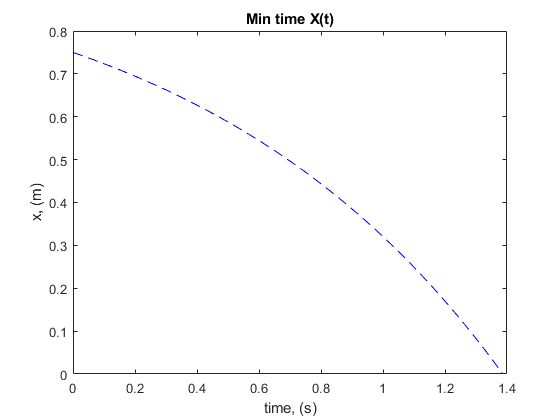

clear
close all
clc

x_0 = 0.75;

t_f = -log(1-x_0);

t = linspace(0,t_f);

x = 1-exp(t-t_f);

figure(1)

plot(t, x, '--b');
xlabel('time, (s)')
ylabel('x, (m)')
title('Min time X(t)')

syms t
nu = 2*exp(t-2);
x_o = .75

x_o = 0.7500

eqn = 1+(x_o-1)*exp(t) == -nu/4*(exp(t-2)-exp(2-t));

t1 = solve(eqn,t);

nu = double(subs(nu,t,t1(2)))

nu = 0.5882


t1 = double(t1(2))

t1 = 0.7761


J = t1 - (nu^2)/8*(1-exp(2*(2-t1)))

J = 1.2329

clear

## Numerical solutions

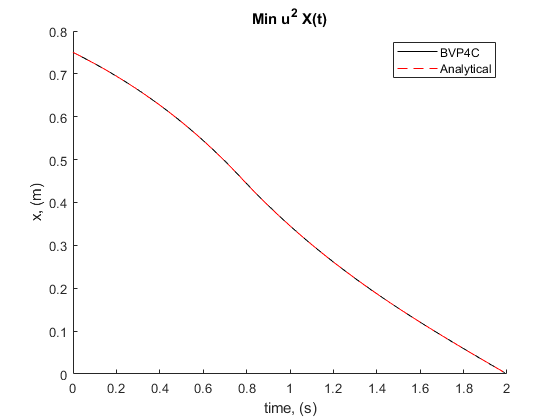

tf = 2;
tflip = flip(linspace(0,tf,tf*100+1));

options = odeset('Events',@satEvent);
[T,S] = ode45(@(t,s)eom(t,s),tflip,[0,0.58],options);
T = flip(T);
S = flip(S);

[T1,S1] = ode45(@(t,s)eom1(t,s),linspace(0,(tf*100+1-length(T))/100,(tf*100+1-length(T))),[.75,.5882*exp(2)]);


Tc = [T1; T];
Sc = [S1; S];

figure(2)
%plot(Tc,Sc(:,1),'--r')
hold on
solinit.x = T;
solinit.y = S';
solinit1.x = T1;
solinit1.y = S1';
sol = bvp4c(@(tx,sx)ELeom(tx,sx),@bcfunc,solinit);
sol1 = bvp4c(@(tx,sx)ELeom1(tx,sx),@bcfunc1,solinit1);

Ts = [sol1.x sol.x];
Xs = [sol1.y sol.y];

plot(Ts(2:200),Xs(1,2:200),'-k')



t = linspace(0,tf,tf*100+1);
xsat = (.75-1).*exp(t(1:76))+1;
xa = -0.5882/4.*(exp(t(77:201)-2)-exp(2-t(77:201)));
xg = [xsat xa];
l = 0.5882*exp(2-t);
plot(t,xg,'--r');
xlabel('time, (s)')
ylabel('x, (m)')
title('Min u^2 X(t)')
legend('BVP4C', 'Analytical')
hold off

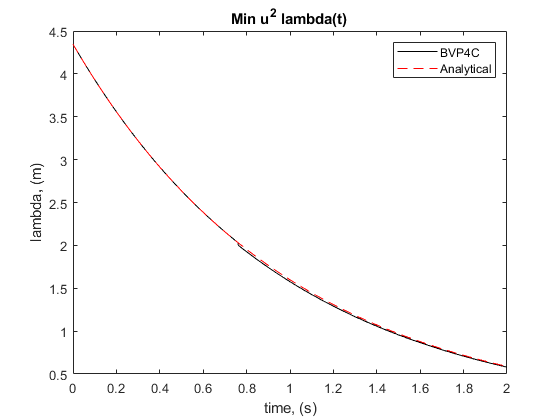

figure(3)
plot(Tc,Sc(:,2),'-k')
hold on
plot(t,l,'--r')
xlabel('time, (s)')
ylabel('lambda, (m)')
title('Min u^2 lambda(t)')
legend('BVP4C', 'Analytical')

% Euler-Lagrange Equations:

function ds = eom(~,s)
% s(1) = x, s(2) = Lambda
u = s(2)/2; % optimal control law, Note: this negative is inconsistent
ds(1) = (s(1)-u); %xdot = x-u
ds(2) = -s(2); %lambda_dot = -lambda
ds = ds'; 
end

function ds = eom1(~,s)
% s(1) = x, s(2) = Lambda
u = 1; % optimal control law
ds(1) = (s(1)-u); %xdot = x-u
ds(2) = -s(2); %lambda_dot = -lambda
ds = ds'; 
end

% Euler-Lagrange Equations:
function ds = ELeom(~,sx)
% sx(1) = x, sx(2) = Lambda
u = sx(2)/2; % optimal control law
ds(1) = sx(1)-u; %xdot = x-u
ds(2) = -sx(2); %lambda_dot = -lambda
ds = ds';
end

% Euler-Lagrange Equations:
function ds = ELeom1(~,sx)
% sx(1) = x, sx(2) = Lambda
u = 1; % optimal control law
ds(1) = sx(1)-u; %xdot = x-u
ds(2) = -sx(2); %lambda_dot = -lambda
ds = ds';
end

% Boundary Condition Function
function con = bcfunc(so,sf)
% so is the initial states
% sf is the final states
con(2) = sf(2)-0.5882; 
con(1) = sf(1);
end

% Boundary Condition Function
function con = bcfunc1(so,sf)
% so is the initial states
% sf is the final states

con(2) = so(2)-0.5882*exp(2); 
con(1) = so(1)-.75;
end

function [position,isterminal,direction] = satEvent(~,s)
position = 1-s(2)/2; %when u becomes saturated
direction = 0;
isterminal = 1; %halting integration
end